# Show  Diagram FP demo

Use ShowDiagramFP function to show the Fuel-Product diagram.

### **Read Data Model**

file = "C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\tgas\tgas_model.json";
data = ReadDataModel(file);

### **Build Diagram FP**

Get the DiagramFP results info and save it into a file

res=DiagramFP(data,'SaveAs','DiagramFP.xlsx');

INFO: cMessageLogger. Diagram FP is saved in file DiagramFP.xlsx


### Plot Diagram FP

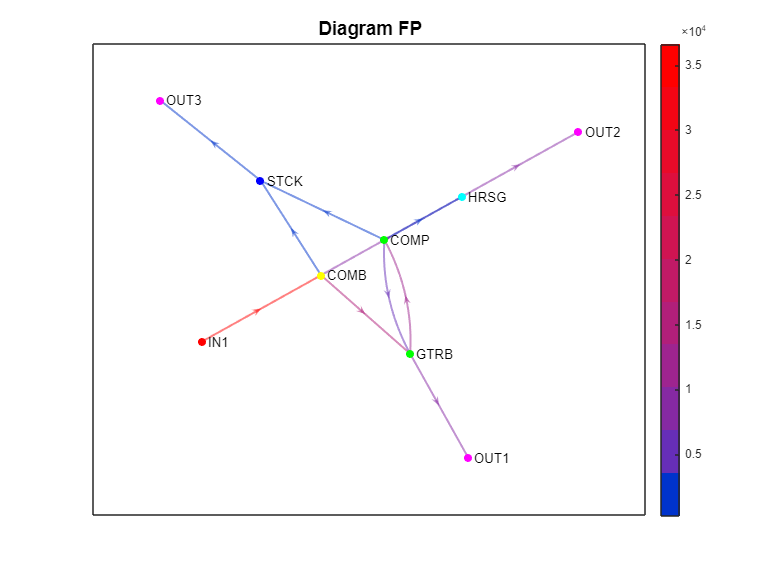

ShowGraph(res,'Graph',cType.Tables.DIGRAPH_FP);

ShowResults(res,'Table',cType.Tables.TABLE_FP);


FP Table (kW) - Reference

 Key           COMB      COMP      GTRB      HRSG      STCK       ENV     Total
————————————————————————————————————————————————————————————————————————————————
 COMB           0.0       0.0   15146.5    7737.1     594.5       0.0   23478.0
 COMP           0.0       0.0    6136.5    3134.6     240.8       0.0    9512.0
 GTRB           0.0   10225.0       0.0       0.0       0.0   10000.0   20225.0
 HRSG           0.0       0.0       0.0       0.0       0.0    7168.0    7168.0
 STCK           0.0       0.0       0.0       0.0       0.0     835.3     835.3
 ENV        36620.0       0.0       0.0       0.0       0.0       0.0   36620.0
————————————————————————————————————————————————————————————————————————————————
 Total      36620.0   10225.0   21283.0   10871.7     835.3   18003.3          



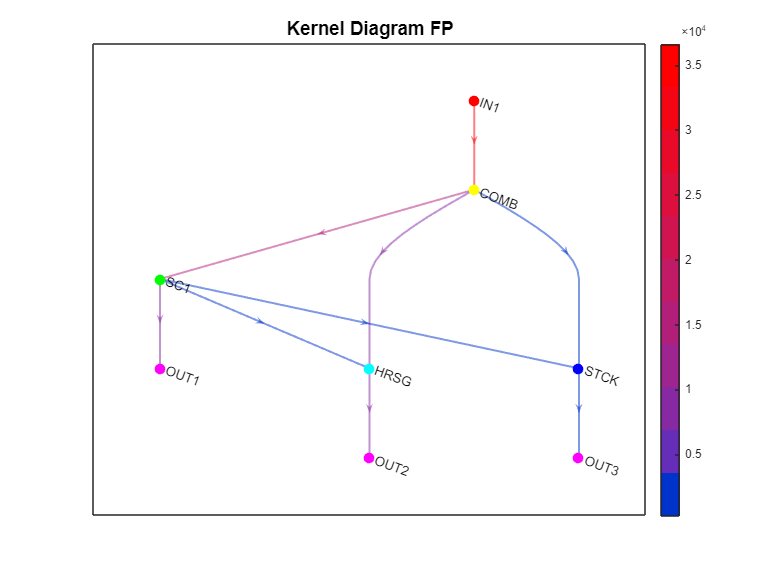

ShowGraph(res,'Graph',cType.Tables.KDIGRAPH_FP);

ShowResults(res,'Table',cType.Tables.KTABLE_FP);


Kernel FP Table (kW) - Reference

 Key           COMB       SC1      HRSG      STCK       ENV     Total
——————————————————————————————————————————————————————————————————————
 COMB           0.0   15146.5    7737.1     594.5       0.0   23478.0
 SC1            0.0       0.0    3134.6     240.8   10000.0   13375.5
 HRSG           0.0       0.0       0.0       0.0    7168.0    7168.0
 STCK           0.0       0.0       0.0       0.0     835.3     835.3
 ENV        36620.0       0.0       0.0       0.0       0.0   36620.0
——————————————————————————————————————————————————————————————————————
 Total      36620.0   15146.5   10871.7     835.3   18003.3          



ShowResults(res,'Table',cType.Tables.PROCESS_GROUP)


Graph Components - Reference

Key   Group  
——————————————
IN1   IN     
COMB  COMB   
COMP  SC1    
GTRB  SC1    
HRSG  HRSG   
STCK  STCK   
OUT1  OUT    
OUT2  OUT    
OUT3  OUT    



### Plot Cost Table FP

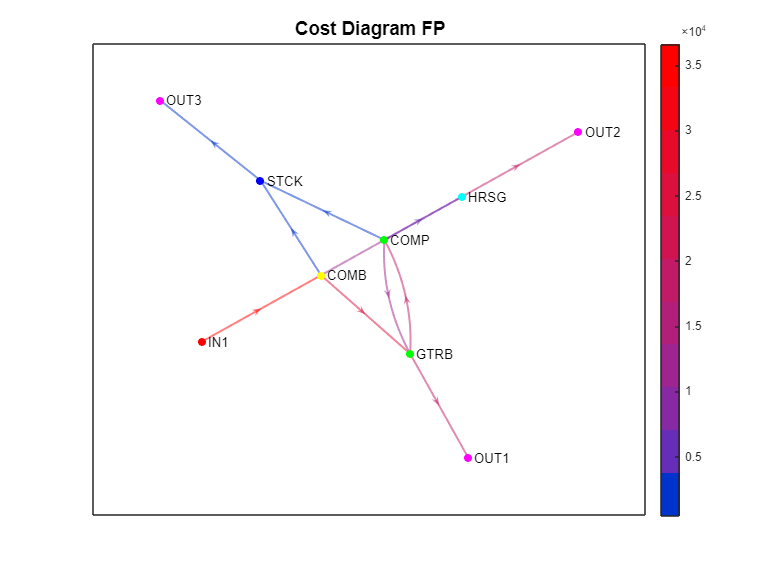

ShowGraph(res,'Graph',cType.Tables.DIGRAPH_COST_FP);

ShowResults(res,'Table',cType.Tables.COST_TABLE_FP);


FP Exergy Cost Table (kW) - Reference

 Key           COMB      COMP      GTRB      HRSG      STCK       ENV     Total
————————————————————————————————————————————————————————————————————————————————
 COMB           0.0       0.0   23624.8   12067.9     927.2       0.0   36620.0
 COMP           0.0       0.0   11435.0    5841.2     448.8       0.0   17724.9
 GTRB           0.0   17724.9       0.0       0.0       0.0   17334.9   35059.8
 HRSG           0.0       0.0       0.0       0.0       0.0   17909.1   17909.1
 STCK           0.0       0.0       0.0       0.0       0.0    1376.0    1376.0
 ENV        36620.0       0.0       0.0       0.0       0.0       0.0   36620.0
————————————————————————————————————————————————————————————————————————————————
 Total      36620.0   17724.9   35059.8   17909.1    1376.0   36620.0          



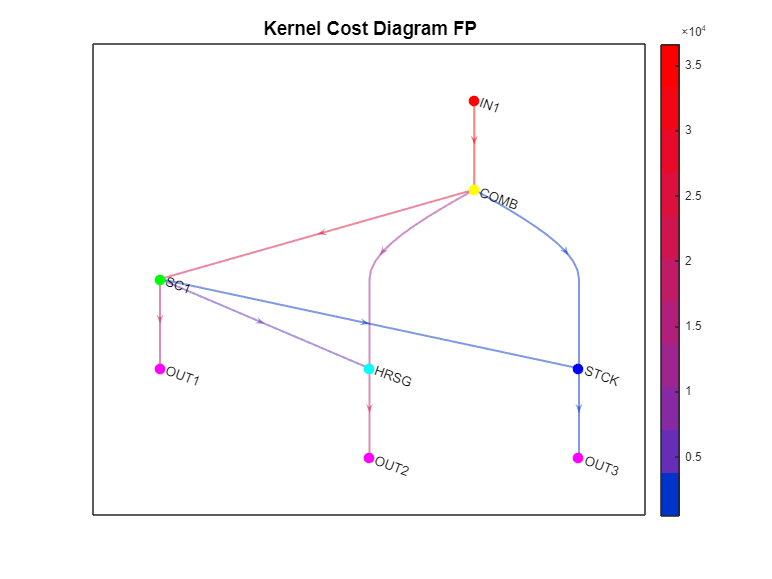

ShowGraph(res,'Graph',cType.Tables.KDIGRAPH_COST_FP);

ShowResults(res,'Table',cType.Tables.KTABLE_COST_FP);


Kernel FP Exergy Cost Table (kW) - Reference

 Key           COMB       SC1      HRSG      STCK       ENV     Total
——————————————————————————————————————————————————————————————————————
 COMB           0.0   23624.8   12067.9     927.2       0.0   36620.0
 SC1            0.0       0.0    5841.2     448.8   17334.9   23624.8
 HRSG           0.0       0.0       0.0       0.0   17909.1   17909.1
 STCK           0.0       0.0       0.0       0.0    1376.0    1376.0
 ENV        36620.0       0.0       0.0       0.0       0.0   36620.0
——————————————————————————————————————————————————————————————————————
 Total      36620.0   23624.8   17909.1    1376.0   36620.0          



### Additional Help Information

help DiagramFP

 DiagramFP - Generate annotated fuel-product diagrams with exergy flows and costs.
    Creates comprehensive fuel-product (FP) diagrams that combine productive
    structure with calculated exergy flows and direct costs for a specific
    operating state. These diagrams can be visualized interactively using
    ShowGraph() or exported for professional graph layout software (yEd, Graphviz).
 
    FP diagrams extend productive structure by adding quantitative information:
      • Exergy flow magnitudes (kW, MW, etc.)
      • Direct exergy costs (kW/kW, dimensionless)
      • Process fuel and product values
      • Component-based grouping for complex systems
      • Both detailed and simplified kernel representations
    These tables support:
      • State-specific performance visualization
      • Exergy flow tracking through system
      • Direct cost formation analysis
      • Interactive diagram exploration with ShowGraph()
      • Export to professional layout softw